clc
clear
l = 0.092;
m_R = 0.412;
J_R = 8.9*10^-3;
B_R = 2.2*10^-3;
m_H = 0.220;
J_H = 0.694*10^-3;
B_H = 0.199*10^-6;
g = 9.82;

p1 = (-B_R) / (J_R-m_H*l^2);
p2 = B_H / (J_R-m_H*l^2);
p3 = (l*(m_R+m_H)*g) / (J_R-m_H*l^2);
p4 = 1 / (J_R-m_H*l^2);
p5 = 1 / J_H;
p6 = B_H/J_H;

A = [0 1 0 ; p3 p1 p2 ; -p3 -p1 -(p6+p2)]

A =          0    1.0000         0
   81.1282   -0.3126    0.0000
  -81.1282    0.3126   -0.0003


B = [0 ; -p4 ; p5+p4]

B = 1.0e+03 *

         0
   -0.1421
    1.5830


C = [1 0 0 ; 0 1 0 ; 0 0 1]

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3,1)

D =      0
     0
     0


cond(A)

ans = 5.6586e+05

cond(B)

ans = 1

cond(C)

ans = 1

cond(D)

ans = Inf


Co = ctrb(A,B)

Co = 1.0e+04 *

         0   -0.0142    0.0044
   -0.0142    0.0044   -1.1541
    0.1583   -0.0045    1.1541


rank(Co)

ans = 3

cond(Co)

ans = 115.3348

O = obsv(A,C)

O =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
         0    1.0000         0
   81.1282   -0.3126    0.0000
  -81.1282    0.3126   -0.0003
   81.1282   -0.3126    0.0000
  -25.3624   81.2260   -0.0000
   25.3856  -81.2261    0.0000


rank(O)

ans = 3

cond(O)

ans = 151.1899


k = [-1.1536 -0.1998 -0.0015];
Acl = A-B*k;
eig(Acl)

ans =  -23.1018 + 0.0000i
  -1.6128 + 2.2334i
  -1.6128 - 2.2334i


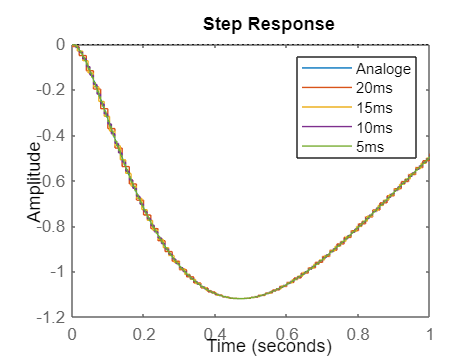

G = ss(A-B*k,B,C,D);

D1 = c2d(G(1,1), 0.020,'tutsin');
D2 = c2d(G(1,1), 0.015,'tutsin');
D3 = c2d(G(1,1), 0.010,'tutsin');
D4 = c2d(G(1,1), 0.005,'tutsin');


step(G(1,1), D1, D2, D3, D4)
legend("Analoge", "20ms", "15ms", "10ms", "5ms")
xlim([0 1])

## Tilstandsregulering VS frekvens(lead-lag)

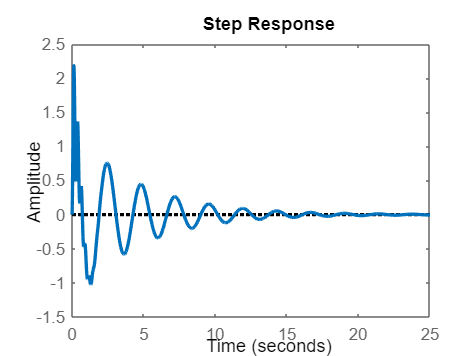

s=tf('s');
Plant = (-142.086 * s)/(s^3 + 0.313*s^2-81.131*s-0.023);
LeadLag = -5*((s+1)*(s+0.001))/((s+10)*(s-5));
T = feedback(LeadLag*Plant,1);


k_1 = -0.0005;
k_2 = -1;
k_3 = -0.1;
num = (-s/(J_R - m_H *l^2));
denum = s^3 + ((-k_3+(B_R-B_H))/(J_R - m_H *l^2) + (B_H+k_1)/(J_H))*s^2 + ( (-k_2 - l*g*(m_R + m_H))/(J_R - m_H *l^2) + ((B_R-B_H)*(B_H+k_1))/((J_R - m_H *l^2)*J_H) )*s + (-l*g*(m_R+m_H)*(B_H+k_1))/((J_R - m_H *l^2)*J_H);
H3 = num / denum;


step(T)
set(findall(gcf,'type','line'),'linewidth',2);
saveas(gcf,'Stepresponse_LeadLag','epsc');

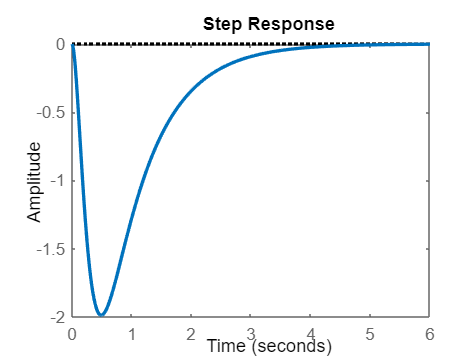


step(H3)
set(findall(gcf,'type','line'),'linewidth',2);
saveas(gcf,'Stepresponse_Cascade','epsc');

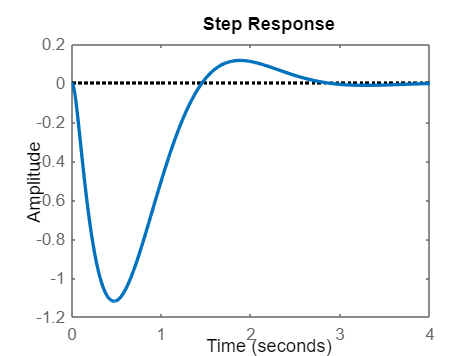


step(G(1,1))
set(findall(gcf,'type','line'),'linewidth',2);
saveas(gcf,'Stepresponse_SS','epsc');